**Project - Equations of motion matlab script**

**Initialize**

clc;
clear;
% syms mc mp x dx l th dth g F Fcart Fpend ddx ddth s Fdist bc bp
mc=0.9+0.1; 
mp=0.08887;
%l = 0.175;
l= 0.36022/2;
g = 9.82;
bc = 8.5;
bp = 0.0012;

v = sqrt(0.08589/(1.225*0.37*0.012*0.47))

v = 5.7965

**Without Disturbance linear**

 %E = [(mc+mp)*ddx == (mp*l*ddth)/2 + F - bc*dx, (mp*l^2*ddth)/4 == (mp*ddx*l)/2 + (mp*g*l*th)/2 - bp*dth];
 %E = [(mc+mp)*ddx - mp*l*ddth == F - bc*dx, mp*l^2*ddth + mp*ddx*l - mp*g*l*th == -Fdist - bp*dth];
%  E = [(mc+mp)*ddx - mp*l*ddth == F - bc*dx, mp*l^2*ddth + mp*ddx*l - mp*g*l*th == - bp*dth];
%  S0 = solve(E,ddx,ddth);
%  S0.ddx
%  temp_x = -((bc*l)/(l*(mc+2*mp)))*dx   + ((g*l*mp)/(l*(mc+2*mp)))*th    - ((bp)/(l*(mc+2*mp)))*dth   + (l/(l*(mc+2*mp)))*F %- ((1)/(l*(mc+2*mp)))*Fdist
%  simplify(temp)
 
%  S0.ddth
%  temp_th = ((bc*l*mp)/(l^2*mp*(mc+2*mp)))*dx   + ((g*l*mp*(mp+mc))/(l^2*mp*(mc+2*mp)))*th    - ((bp*(mc+mp))/(l^2*mp*(mc+2*mp)))*dth    - (l*mp/(l^2*mp*(mc+2*mp)))*F %- ((mc-mp)/(l^2*mp*(mc+2*mp)))*Fdist
%  simplify(temp)



**With Disturbance linaer**

% E1 = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fdist-Fpend];
% S1 = solve(E1,ddx,ddth);
% S1.ddx;
% S1.ddth;

**Nonlinear**

% E2 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-Fcart, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -Fpend];
% S2 = solve(E2, ddx, ddth);
% S2.ddx;
% S2.ddth;

**Fpend and Fcart are b * x/th**

% E3 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-b*dx, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -b*dth];
% S3 = solve(E3, ddx, ddth);
% S3.ddx;
% S3.ddth;

**State Space Model**

C = [0 1 0 0;
     1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
% A = [0 0 1 0;
%      0 0 0 1;
%      0 ((g*l*mp)/(l*(mc+2*mp))) -((bc*l)/(l*(mc+2*mp))) -((bp)/(l*(mc+2*mp)));
%      0 ((g*l*mp*(mp+mc))/(l^2*mp*(mc+2*mp))) ((bc*l*mp)/(l^2*mp*(mc+2*mp))) -((bp*(mc+mp))/(l^2*mp*(mc+2*mp)))]


A = [0 0 1 0;
     0 0 0 1;
     0 -(g*mp)/(mc+2*mp) 0 0;
     0 -(g*(mp+mc))/(l*(mc+2*mp)) 0 0]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -0.7410         0         0
         0  -50.4081         0         0


 
 %*dx   + *th    -*dth  - *Fdist   + *F
 %*dx   + *th    -*dth   - *Fdist   -*F
 
  
B = [0 0;
     0 0;
     1/(mc+2*mp) l/(l*(mc+2*mp));
     -1/(l*(mc+2*mp)) -(mc+mp)/(l^2*mp*(mc+2*mp))]

B =          0         0
         0         0
    0.8491    0.8491
   -4.7143 -320.6976



% B = [0 0;
%      0 0;
%      (1/((mc+2*mp))) (1/(l*(mc+2*mp)));
%      -(1/(l*(mc+2*mp))) -((mc-mp)/(l^2*mp*(mc+2*mp)))]

 %u = [F; 0];
 
system = ss(A,B,C,0)

system =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -0.741       0       0
   x4       0  -50.41       0       0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3  0.8491  0.8491
   x4  -4.714  -320.7
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Observability and Controlability**

observability = obsv(system)

observability =          0    1.0000         0         0
    1.0000         0         0         0
         0         0         0    1.0000
         0         0    1.0000         0
         0  -50.4081         0         0
         0   -0.7410         0         0
         0         0         0  -50.4081
         0         0         0   -0.7410


%rank(observability); % Full rank
symObs = [ C     ; 
           C*A   ;
           C*A^2 ;
           C*A^3 ]

symObs =          0    1.0000         0         0
    1.0000         0         0         0
         0         0         0    1.0000
         0         0    1.0000         0
         0  -50.4081         0         0
         0   -0.7410         0         0
         0         0         0  -50.4081
         0         0         0   -0.7410


ObsRank = rank(symObs)

ObsRank = 4


controlability = ctrb(system)

controlability = 	1.0e+04 *

         0         0    0.0001    0.0001         0         0    0.0003    0.0238
         0         0   -0.0005   -0.0321         0         0    0.0238    1.6166
    0.0001    0.0001         0         0    0.0003    0.0238         0         0
   -0.0005   -0.0321         0         0    0.0238    1.6166         0         0


%rank(controlability); % Full rank
symCon = [B, A*B, A^2*B, A^3*B]

symCon = 	1.0e+04 *

         0         0    0.0001    0.0001         0         0    0.0003    0.0238
         0         0   -0.0005   -0.0321         0         0    0.0238    1.6166
    0.0001    0.0001         0         0    0.0003    0.0238         0         0
   -0.0005   -0.0321         0         0    0.0238    1.6166         0         0


ConRank = rank(symCon)

ConRank = 4

## **Pole Placement Method**

**Extended Matrices**

A_e = [A zeros([4 2]);
       C zeros([2 2])]

A_e =          0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0   -0.7410         0         0         0         0
         0  -50.4081         0         0         0         0
         0    1.0000         0         0         0         0
    1.0000         0         0         0         0         0


B_e = [B;
       zeros([2 2])];
C_e = [C zeros([2 2])];

**Pole Placement - settling of +/-3% in 1 second.**

ts = 1;
alpha = 3;
sigma = -log10(alpha/100)/ts

sigma = 1.5229


poles = -[sigma+1i sigma-1i sigma*5+1i sigma*5-1i sigma*6+1i sigma*6-1i]

poles =   -1.5229 - 1.0000i  -1.5229 + 1.0000i  -7.6144 - 1.0000i  -7.6144 + 1.0000i  -9.1373 - 1.0000i  -9.1373 + 1.0000i


% Tried to plot with poles on the real axis. This did not work either.
% poles = -[sigma sigma*5 sigma*7 sigma*12 sigma*18 sigma*22]

Fe = -place(A_e, B_e, poles);
F = Fe(1:2, 1:4)

F =  -106.5624   56.4797  -21.3018    3.1784
    1.5919   -0.6655    0.3143    0.0117


Fi = Fe(1:2, 5:6)

Fi =   227.9819  -92.3426
   -2.9316    1.4578



% feedback = A_e + B_e * Fe;
% eigMat = eig(A_e + B_e * Fe);

## 3. Observer design

Pole selection

OBS = [-sigma*5.1+1i -sigma*5.1-1i -sigma*6.1+1i -sigma*6.1-1i]

OBS =   -7.7667 + 1.0000i  -7.7667 - 1.0000i  -9.2896 + 1.0000i  -9.2896 - 1.0000i


%OBS = [OBS1-0.1 OBS1-0.2 OBS1-0.3 OBS1-0.4];

Observer design    

L = -place(system.A', system.C', OBS).'

L =    -0.0185  -17.0321
  -17.0804   -0.0185
    2.1056  -72.9438
  -22.9471   -1.6809


Anti windup

MP = [-sigma*5.5+1i -sigma*5.5-1i -sigma*6.5+1i -sigma*6.5-1i]

MP =   -8.3758 + 1.0000i  -8.3758 - 1.0000i  -9.8987 + 1.0000i  -9.8987 - 1.0000i


%MP = [-15 -20 -25 -30]
M = -place((A + L * C)', F', MP).'

M =     0.0030   -0.0761
   -0.0276   -1.9050
   -0.0385   -5.0582
   -0.2363  -15.6156


## **Transfer functions and PID controller **

## **Not used yet.**

SA = inv(S-A)

SA =
 
  From input 1 to output...
       1
   1:  -
       s
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
                         -0.741 s - 1.431e-14
   1:  ---------------------------------------------------------
       s^4 + 3.442e-15 s^3 + 50.41 s^2 - 8.372e-14 s - 3.738e-16
 
             s - 3.65e-15
   2:  -------------------------
       s^2 - 4.154e-15 s + 50.41
 
                 -0.741 s - 9.917e-14
   3:  ----------------------------------------
       s^3 + 5.84e-16 s^2 + 50.41 s + 1.326e-13
 
                -50.41
   4:  -------------------------
       s^2 - 4.154e-15 s + 50.41
 
  From input 3 to output...
                     1
   1:  -----------------------------
       s^2 + 2.629e-15 s - 6.708e-17
 
   2:  0
 
       1
   3:  -
       s
 
   4:  0
 
  From input 4 to output...
                                -0.741
   1:  ---------------------------------------------------------
       s^4 + 1.187e-14 s^3 + 50.41 s^2 + 5.005e-13 s - 8.506e-14
 

% G8 = C*SA*B

[Gnum,Gden] = ss2tf(A,B,C,[0 0; 0 0], 1)

Gnum =          0         0   -4.7143         0   -0.0000
         0         0    0.8491   -0.0000   46.2939


Gden =     1.0000         0   50.4081         0         0


SS2TF1 = Gnum(1,:);
SS2TF2 = Gnum(2,:);
 
G1 =tf(SS2TF1, Gden)

G1 =
 
  -4.714 s^2 - 3.14e-15
  ---------------------
     s^4 + 50.41 s^2
 
Continuous-time transfer function.



G2 =tf(SS2TF2, Gden)

G2 =
 
  0.8491 s^2 - 5.058e-15 s + 46.29
  --------------------------------
          s^4 + 50.41 s^2
 
Continuous-time transfer function.



**PID**

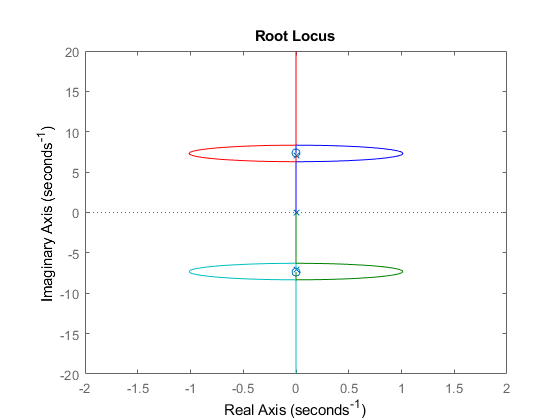

Kp = 50;
Ti = 0.1;
Td = 0.1;

Ks = Kp * (1 + 1 / (Ti * s) + Td * s);
figure
rlocus(G2);

% step(Ks*G2);

% pid(Kp,Ti,Td)


% rlocus(G1);
% rlocus(G2);
% It uses rational numbers instead of decimals.
%  G = C*inv((s-A))*B*u
%  simplify(G);

Output from simulink

% fig1 = figure('Name','Nonlinear test with 10s disturbance');
fig1 = figure('Name', 'Nonlinear test with 0.1s disturbance','Position', [1 1 2560/1.7 1440/1.2]);

subplot(3,2,1);
plot(out.cart_pos,'r', 'LineWidth',2);

grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Position [m]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart position','Interpreter','latex','FontSize', 16)
% ylim([-0.8 0.8])
legend('$x_c$','Interpreter','latex','FontSize', 16)


subplot(3,2,3);
plot(out.cart_vel,'Color',[0 0.65 0],'LineWidth',2);

grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [m/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart velocity','Interpreter','latex','FontSize', 16)
% ylim([-2 2])
legend('$\dot{x_c}$','Interpreter','latex','FontSize', 16)


subplot(3,2,5);
plot(out.cart_acc,'b', 'LineWidth',2);

grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [m/s$^2$]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart acceleration','Interpreter','latex','FontSize', 16)
% ylim([-8 8])
legend('$\ddot{x_c}$','Interpreter','latex','FontSize', 16)


subplot(3,2,2);
plot(out.pend_angle, 'r', 'LineWidth',2);

title('Pendulum angle');
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Angle [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angle','Interpreter','latex','FontSize', 16)
% ylim([-0.8 0.8])
legend('$\theta$','Interpreter','latex','FontSize', 16)


subplot(3,2,4);
plot(out.pend_vel,'Color',[0 0.65 0], 'LineWidth',2);

grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [rad/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angular velocity','Interpreter','latex','FontSize', 16)
% ylim([-2 2])
legend('$\dot{\theta}$','Interpreter','latex','FontSize', 16)


subplot(3,2,6);
plot(out.pend_acc,'b', 'LineWidth',2);

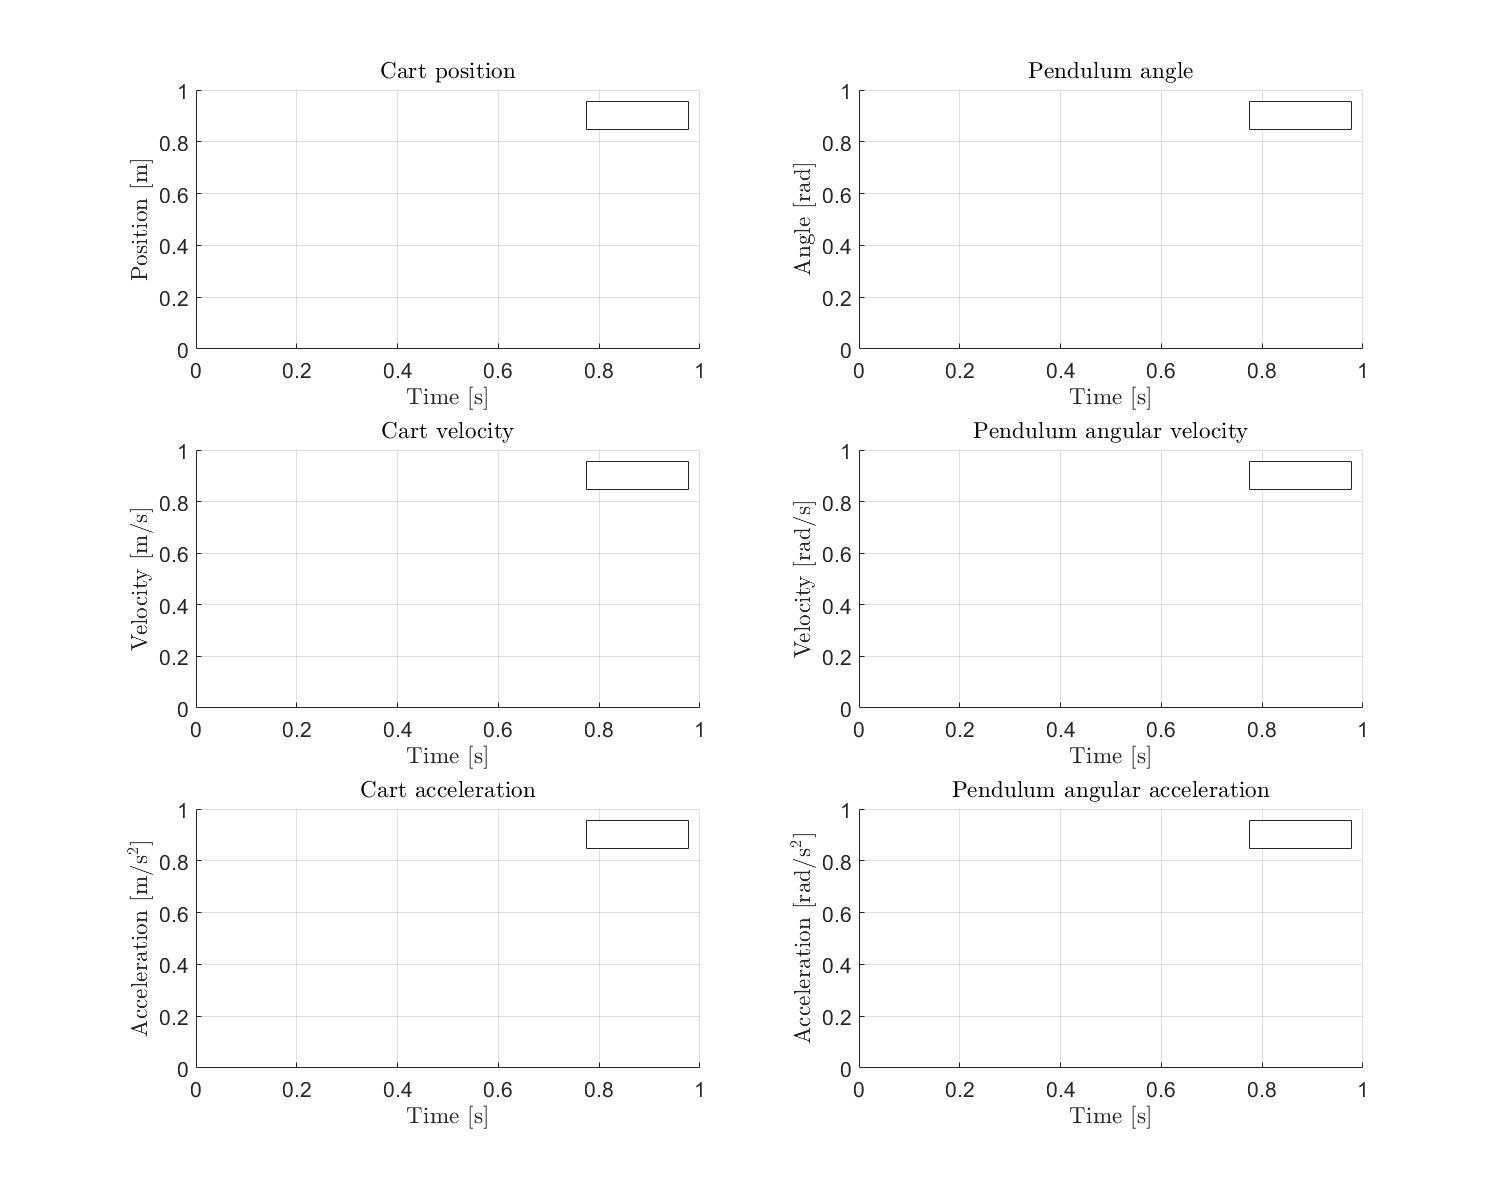

grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [rad/s$^2$]','Interpreter','latex', 'FontSize', 16)
title('Pendulum angular acceleration','Interpreter','latex','FontSize', 16)
% ylim([-8 8])
set(gca,'FontSize',16)
legend('$\ddot{\theta}$','Interpreter','latex','FontSize', 16)

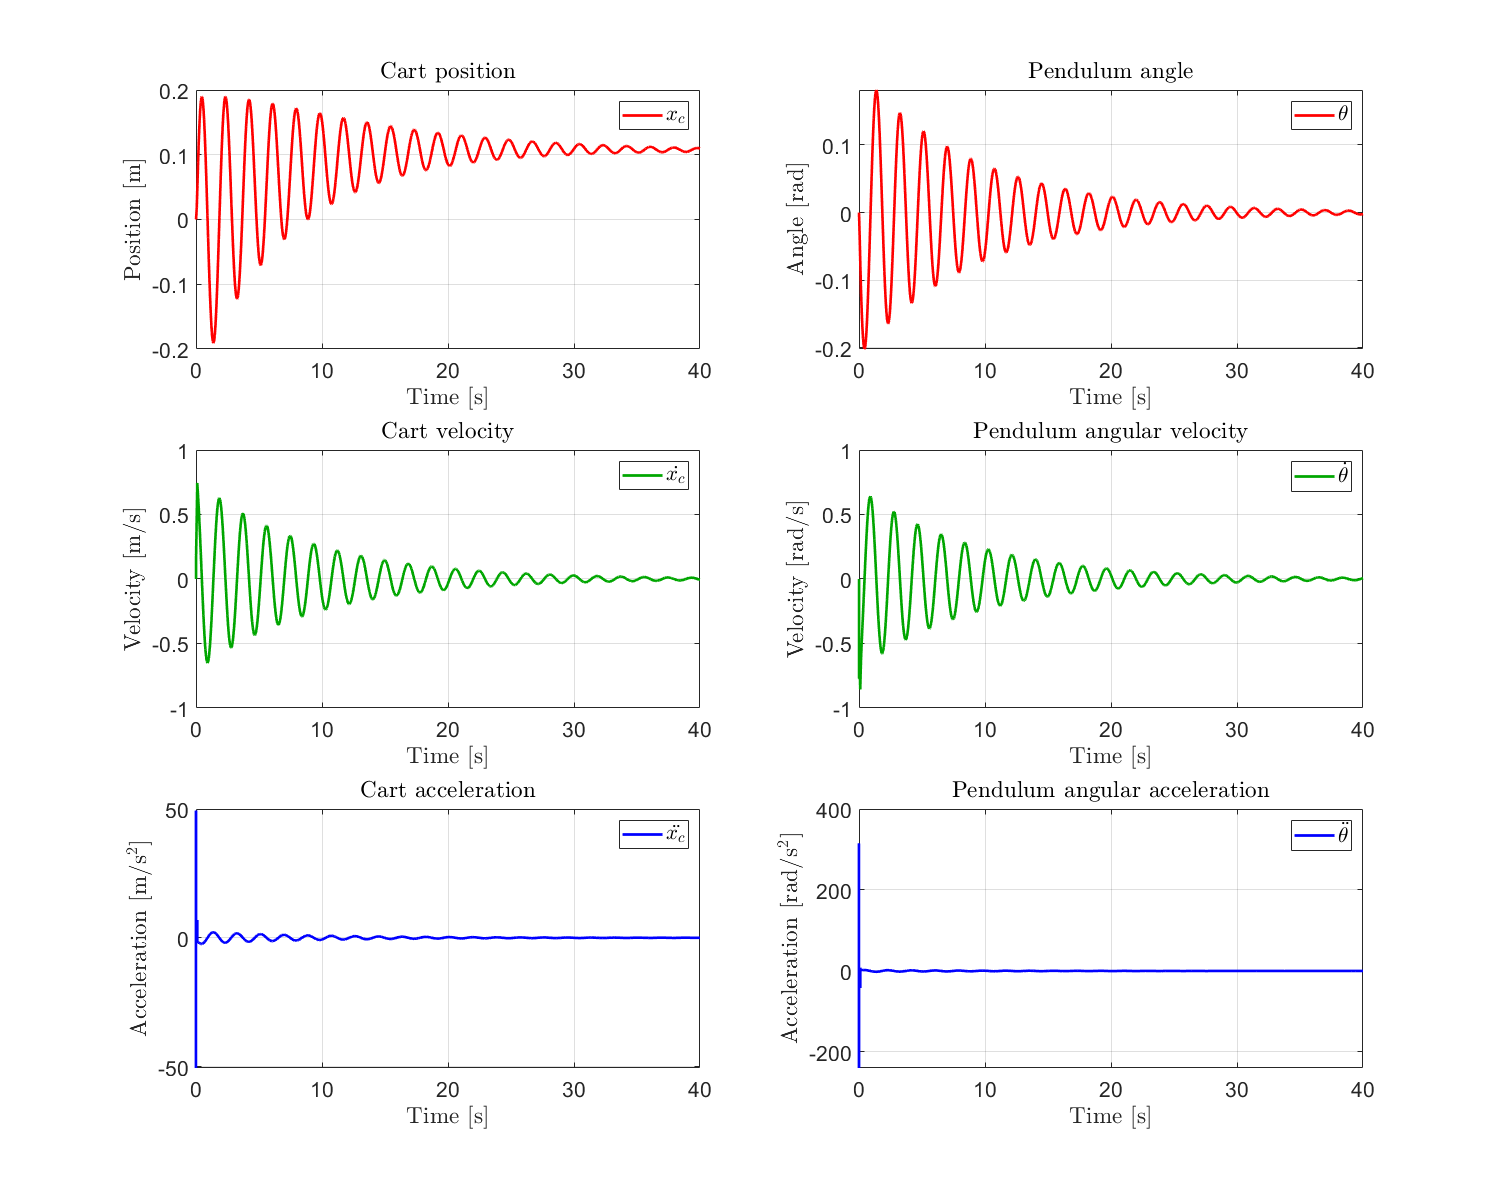


fig2 = figure('Name', 'Linear test with 10s disturbance','Position', [1 1 2560/1.7 1440/1.2]);

subplot(3,2,1);
plot(out.cart_pos_lin,'r', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Position [m]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart position','Interpreter','latex','FontSize', 16)
% ylim([-0.8 0.8])
legend('$x_c$','Interpreter','latex','FontSize', 16)

subplot(3,2,3);
plot(out.cart_vel_lin,'Color',[0 0.65 0],'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [m/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart velocity','Interpreter','latex','FontSize', 16)
% ylim([-2 2])
legend('$\dot{x_c}$','Interpreter','latex','FontSize', 16)

subplot(3,2,5);
plot(out.cart_acc_lin,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [m/s$^2$]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Cart acceleration','Interpreter','latex','FontSize', 16)
% ylim([-8 8])
legend('$\ddot{x_c}$','Interpreter','latex','FontSize', 16)

subplot(3,2,2);
plot(out.pend_angle_lin, 'r', 'LineWidth',2);
title('Pendulum angle');
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Angle [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angle','Interpreter','latex','FontSize', 16)
% ylim([-0.8 0.8])
legend('$\theta$','Interpreter','latex','FontSize', 16)

subplot(3,2,4);
plot(out.pend_vel_lin,'Color',[0 0.65 0], 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Velocity [rad/s]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Pendulum angular velocity','Interpreter','latex','FontSize', 16)
% ylim([-2 2])
legend('$\dot{\theta}$','Interpreter','latex','FontSize', 16)

subplot(3,2,6);
plot(out.pend_acc_lin,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Acceleration [rad/s$^2$]','Interpreter','latex', 'FontSize', 16)
title('Pendulum angular acceleration','Interpreter','latex','FontSize', 16)
% ylim([-8 8])
set(gca,'FontSize',16)
legend('$\ddot{\theta}$','Interpreter','latex','FontSize', 16)

% saveas(fig1,'figures/Exp1Nonlinear', 'png')
%saveas(fig2,'figures/Linear0To1', 'png')

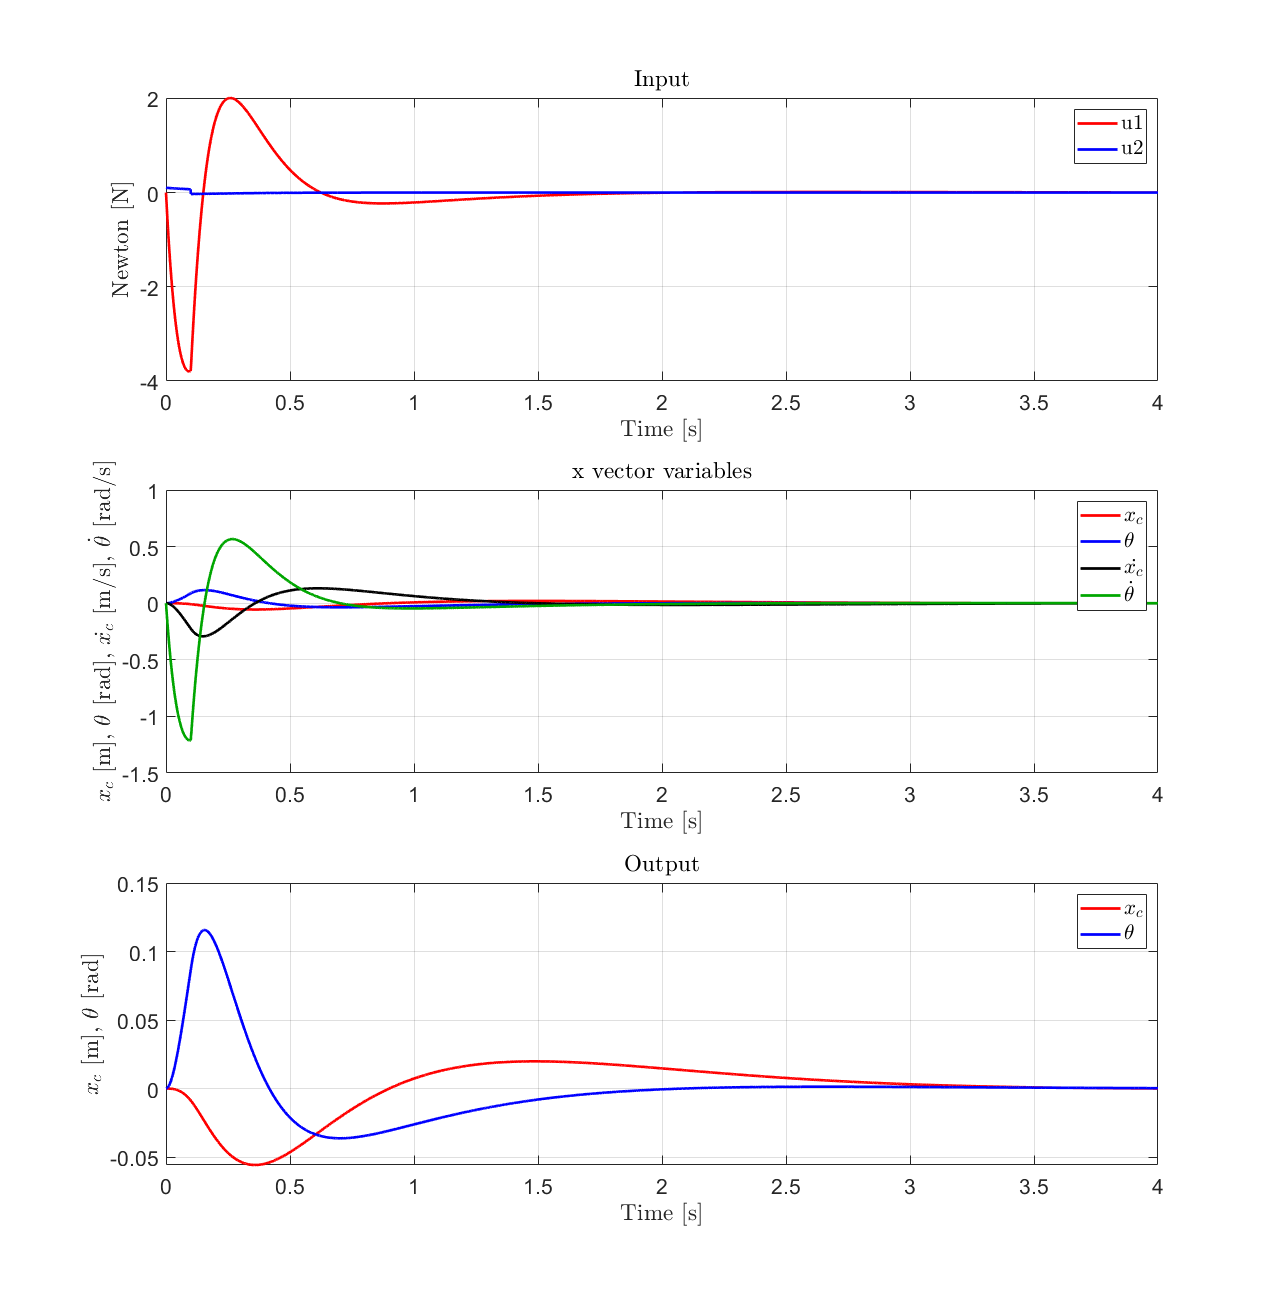

testPlot = out.y1;
testPlot = testPlot *-1;

testPlot1 = out.th;
testPlot1 = testPlot1 *-1;

fig3 = figure('Name', 'Integral Control','Position', [1 1 2560/2 1440/1.1]);

subplot(3,1,1);
plot(out.u1,'r', 'LineWidth',2);
hold on
plot(out.u2,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('Newton [N]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Input','Interpreter','latex','FontSize', 16)
% ylim([-0.8 0.8])
legend('u1','u2','Interpreter','latex','FontSize', 16)

subplot(3,1,2);
plot(out.x,'r', 'LineWidth',2);
hold on
plot(testPlot1,'b','LineWidth',2);
plot(out.dx,'Color',[0 0 0],'LineWidth',2);
plot(out.dth,'Color',[0 0.65 0],'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('$x_c$ [m], $\theta$ [rad], $\dot{x_c}$ [m/s], $\dot{\theta}$ [rad/s]','Interpreter','latex', 'FontSize', 16)
%  , '
set(gca,'FontSize',16)
title('x vector variables','Interpreter','latex','FontSize', 16)
% ylim([-2 2])
legend('$x_c$', '$\theta$', '$\dot{x_c}$', '$\dot{\theta}$', 'Interpreter','latex','FontSize', 16)

subplot(3,1,3);
plot(out.y2,'r', 'LineWidth',2);
hold on
plot(testPlot,'b', 'LineWidth',2);
grid on
xlabel('Time [s]','Interpreter','latex', 'FontSize', 16)
ylabel('$x_c$ [m], $\theta$ [rad]','Interpreter','latex', 'FontSize', 16)
set(gca,'FontSize',16)
title('Output','Interpreter','latex','FontSize', 16)
%ylim([-0.05 0.15])
legend('$x_c$','$\theta$','Interpreter','latex','FontSize', 16)

saveas(fig3,'figures/integral_control_no_offset', 'png')